# S1. Recordings from Mic and Sound Playback to P7 and P12 animals

## Chirps

%A1file; no detectable chirps
A2file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P7 Microphone Recordings and Tones\170906_P8_Animal2_\Animal2_spontaneous.mat';
A3file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P7 Microphone Recordings and Tones\170906_P8_Animal3\Animal3_spontaneous.mat';
load(A2file);
load(A3file);

avgEvents(:,:,1) = mean(Animal2.events,3);
avgEvents(:,:,2) = mean(Animal2.events,3);
avgEvent = mean(avgEvents,3);

lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;
fig1 = figure;
time = [0:size(avgEvent,1)-1]/10;
plot(time,avgEvent(:,1),'Color',lt_org); hold on;
plot(time,avgEvent(:,2),'Color',lt_blue); 
xlim([0 10]);
ylim([0 0.3]);
box off;
fig1.Units = 'inches';
fig1.Position = [0 0 1 1];
fig1.Renderer = 'Painters';
fig1.PaperPositionMode = 'auto';

## vocalization panel

a2file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P7 Microphone Recordings and Tones\170906_P8_Animal2_\Spontaneous\170906_Snap25GC6s_P7_120db_1179_01_00.mat';
load(a2file);

%traceStart = 360;
%traceEnd = 450; 
traceStart = 163;
traceEnd = 193;
smLIC = smooth(ICsignal(traceStart*10:traceEnd*10,1),3);
smRIC = smooth(ICsignal(traceStart*10:traceEnd*10,2),3);

lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;

figu = figure; plot([1:size(smLIC,1)]*.1,smLIC,'Color',lt_org); hold on;
plot([1:size(smLIC,1)]*.1,smRIC,'Color',lt_blue);
figu.Units = 'inches';
figu.Position =[2 2 12 3];
xlim([0 30]);
box off;

data = params.soundRecording;
fig = figure; spectrogram(data(traceStart*params.fs:traceEnd*params.fs),1024,500,1024,params.fs,'yaxis');
colormap('hot'); caxis([-110 0]);

yticks([0 48 96]);
fig.Units = 'inches';
fig.Position =[2 2 12 3];


## chirp example


figur = figure; spectrogram(data((traceStart+22.5)*params.fs:(traceEnd-7.35)*params.fs),1024,500,1024,params.fs,'yaxis');
colormap('hot'); caxis([-110 0]);
yticks([0 48 96]);
box off;
figur.Units = 'inches';
figur.Position = [0 0 2 1.5];
figur.Renderer = 'Painters';
figur.PaperPositionMode = 'auto';


## Sound evoked panel

%individual animal files
A1file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P7 Microphone Recordings and Tones\170825_P7_Animal1\Animal1_sound.mat';
A2file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P7 Microphone Recordings and Tones\170906_P8_Animal2_\Animal2_sound.mat';
A3file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P7 Microphone Recordings and Tones\170906_P8_Animal3\Animal3_sound.mat';

load(A1file); %Animal1.
load(A2file); %Animal2.
load(A3file); %Animal3.

%16 freq log spaced from 3 to 96kHz were played

%individual example is animal 2
sigL = Animal2.LICsig;
sigR = Animal2.RICsig;
avgLIC = squeeze(mean(sigL,1))';
avgRIC = squeeze(mean(sigR,1))';
offset = 0.3;
%offset traces on y axis
for i = 1:10
    copySigL(i,:,:) = sigL(i,:,:) - (i+.25)*offset;
    copySigR(i,:,:) = sigR(i,:,:) - (i+.25)*offset;
end
    
    
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;

    
fig = figure;
for i = 1:16
    subplot(1,16,i);
    
    plot(copySigL(:,:,i)','Color',lt_org,'LineWidth',0.5);
 
    hold on;
    plot(copySigR(:,:,i)','Color',lt_blue,'LineWidth',0.5); 
    plot(avgLIC(i,:),'Color',lt_org,'LineWidth',1);
    plot(avgRIC(i,:),'Color',lt_blue,'LineWidth',1);
    ylim([-10*offset-.2 0.5]);
    xlim([0 60]);
    yticklabels('');
       patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none');
    %title([sprintf('%0.3f',sorted(i*params.repeats)/1000) ' kHz']);
    axis off;
end

fig.Units = 'inches';
fig.Position = [0 0 6 2.75];
fig.Renderer = 'Painters';
fig.PaperPositionMode = 'auto';

%%alt figure; split L and R, all traces gray
fig2 = figure;
offset = 0.5
for i = 1:16
    subplot(1,16,i);
    
    plot([sigL(:,:,i)-mean(sigL(:,10:20,i),2)]','Color',[0.8 0.8 0.8],'LineWidth',0.5);
    hold on;
    plot([sigR(:,:,i)-mean(sigR(:,10:20,i),2)-offset]','Color',[0.8 0.8 0.8],'LineWidth',0.5); 
    plot(avgLIC(i,:)-mean(avgLIC(i,10:20)),'Color',lt_org,'LineWidth',1);
    plot(avgRIC(i,:)-mean(avgRIC(i,10:20))-offset,'Color',lt_blue,'LineWidth',1);
    ylim([-.75 0.5]);
    xlim([0 60]);
    yticklabels('');
       patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none');
    %title([sprintf('%0.3f',sorted(i*params.repeats)/1000) ' kHz']);
    axis off;
end
fig2.Units = 'inches';
fig2.Position = [0 0 6 1.5];
fig2.Renderer = 'Painters';
fig2.PaperPositionMode = 'auto';

%%group data
sigL = Animal1.LICsig;
sigR = Animal1.RICsig;
avgLIC(:,:,1) = squeeze(mean(sigL,1))';
avgRIC(:,:,1) = squeeze(mean(sigR,1))';
sigL = Animal2.LICsig;
sigR = Animal2.RICsig;
avgLIC(:,:,2) = squeeze(mean(sigL,1))';
avgRIC(:,:,2) = squeeze(mean(sigR,1))';
sigL = Animal3.LICsig;
sigR = Animal3.RICsig;
avgLIC(:,:,3) = squeeze(mean(sigL,1))';
avgRIC(:,:,3) = squeeze(mean(sigR,1))';
groupAvgLIC = mean(avgLIC,3);
groupAvgRIC = mean(avgRIC,3);

fig3 = figure;
offset = 0.5
for i = 1:16
    subplot(1,16,i);
    plot(squeeze([avgLIC(i,:,:)-mean(avgLIC(i,10:20,:),2)]),'Color',[0.8 0.8 0.8],'LineWidth',0.5);
    hold on;
    plot(squeeze([avgRIC(i,:,:)-mean(avgRIC(i,10:20,:),2)-offset]),'Color',[0.8 0.8 0.8],'LineWidth',0.5); 
    plot(groupAvgLIC(i,:)-mean(groupAvgLIC(i,10:20)),'Color',lt_org,'LineWidth',1);
    plot(groupAvgRIC(i,:)-mean(groupAvgRIC(i,10:20))-offset,'Color',lt_blue,'LineWidth',1);
    ylim([-.75 0.5]);
    xlim([0 60]);
    yticklabels('');
       patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none');
    %title([sprintf('%0.3f',sorted(i*params.repeats)/1000) ' kHz']);
    axis off;
end
fig3.Units = 'inches';
fig3.Position = [0 0 6 1.5];
fig3.Renderer = 'Painters';
fig3.PaperPositionMode = 'auto';

%%P12
A1P12file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P12 Microphone Recordings and Tones\Animal 1_170830\Animal1_p12_sound.mat';
load(A1P12file); %Animal1.
sigL = Animal1_P12.LICsig;
sigR = Animal1_P12.RICsig;

avgLIC = squeeze(mean(sigL,1))';
avgRIC = squeeze(mean(sigR,1))';
offset = 0.3;
%offset traces on y axis
for i = 1:3
    copySigL(i,:,:) = sigL(i,:,:) - (i+.25)*offset;
    copySigR(i,:,:) = sigR(i,:,:) - (i+.25)*offset;
end
    
    
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;

    
fig4 = figure;
offset = 0.5
for i = 1:16
    subplot(1,16,i);
    plot([sigL(:,:,i)-mean(sigL(:,1:10,i),2)]','Color',[0.8 0.8 0.8],'LineWidth',0.5);
    hold on;
    plot([sigR(:,:,i)-mean(sigR(:,1:10,i),2)-offset]','Color',[0.8 0.8 0.8],'LineWidth',0.5); 
    plot(avgLIC(i,:)-mean(avgLIC(i,1:10)),'Color',lt_org,'LineWidth',1);
    plot(avgRIC(i,:)-mean(avgRIC(i,1:10))-offset,'Color',lt_blue,'LineWidth',1);
    ylim([-.75 0.5]);
    xlim([0 60]);
    yticklabels('');
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none');
    %title([sprintf('%0.3f',sorted(i*params.repeats)/1000) ' kHz']);
    axis off;
end

fig4.Units = 'inches';
fig4.Position = [0 0 6 1.5];
fig4.Renderer = 'Painters';
fig4.PaperPositionMode = 'auto';  


## VG3 KO

A1VG3file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P15 VG3 KO\Animal1_p15_VG3.mat';
A2VG3file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P15 VG3 KO\Experiment-1355\ICsignals.mat';
A3VG3file = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\P15 VG3 KO\Experiment-1357\ICsignals.mat';
load(A1VG3file); %Animal1.
load(A2VG3file);
load(A3VG3file);

sigL = Animal1_VG3.LICsig;
sigR = Animal1_VG3.RICsig;
VG3avgLIC(:,:,1) = squeeze(mean(sigL,1))';
VG3avgRIC(:,:,1) = squeeze(mean(sigR,1))';
sigL = VG3Animal2.LICsig;
sigR = VG3Animal2.RICsig;
VG3avgLIC(:,:,2) = squeeze(mean(sigL,1))';
VG3avgRIC(:,:,2) = squeeze(mean(sigR,1))';
sigL = VG3Animal3.LICsig;
sigR = VG3Animal3.RICsig;
VG3avgLIC(:,:,3) = squeeze(mean(sigL,1))';
VG3avgRIC(:,:,3) = squeeze(mean(sigR,1))';

VG3groupAvgLIC = mean(VG3avgLIC,3);
VG3groupAvgRIC = mean(VG3avgRIC,3);



offset = 0.3;
%offset traces on y axis
fig8 = figure;
offset = 0.5

offset = 0.5000

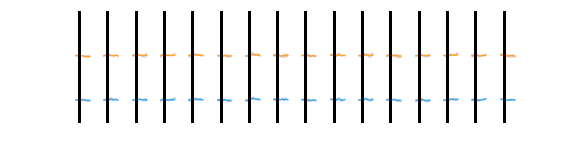

for i = 1:16
    subplot(1,16,i);
    plot(squeeze([VG3avgLIC(i,:,:)-mean(VG3avgLIC(i,10:20,:),2)]),'Color',[0.8 0.8 0.8],'LineWidth',0.5);
    hold on;
    plot(squeeze([VG3avgRIC(i,:,:)-mean(VG3avgRIC(i,10:20,:),2)-offset]),'Color',[0.8 0.8 0.8],'LineWidth',0.5); 
    plot(VG3groupAvgLIC(i,:)-mean(VG3groupAvgLIC(i,10:20)),'Color',lt_org,'LineWidth',1);
    plot(VG3groupAvgRIC(i,:)-mean(VG3groupAvgRIC(i,10:20))-offset,'Color',lt_blue,'LineWidth',1);
    ylim([-.75 0.5]);
    xlim([0 60]);
    yticklabels('');
       patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none');
    %title([sprintf('%0.3f',sorted(i*params.repeats)/1000) ' kHz']);
    axis off;
end
fig8.Units = 'inches';
fig8.Position = [0 0 6 1.5];
fig8.Renderer = 'Painters';

fig8.PaperPositionMode = 'auto';
    
    
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;

    
fig6 = figure;
offset = 0.5

offset = 0.5000

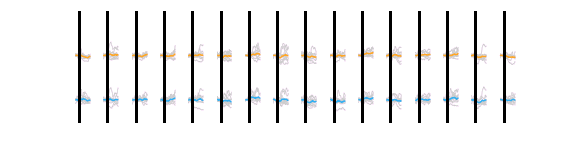

for i = 1:16
    subplot(1,16,i);
    plot([sigL(:,:,i)-mean(sigL(:,1:10,i),2)]','Color',[0.8 0.8 0.8],'LineWidth',0.5);
    hold on;
    plot([sigR(:,:,i)-mean(sigR(:,1:10,i),2)-offset]','Color',[0.8 0.8 0.8],'LineWidth',0.5); 
    plot(avgLIC(i,:)-mean(avgLIC(i,1:10)),'Color',lt_org,'LineWidth',1);
    plot(avgRIC(i,:)-mean(avgRIC(i,1:10))-offset,'Color',lt_blue,'LineWidth',1);
    ylim([-.75 0.5]);
    xlim([0 60]);
    yticklabels('');
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none');
    %title([sprintf('%0.3f',sorted(i*params.repeats)/1000) ' kHz']);
    axis off;
end

fig6.Units = 'inches';
fig6.Position = [0 0 6 1.5];
fig6.Renderer = 'Painters';

fig6.PaperPositionMode = 'auto';
%figQuality(fig6,gca,[6 1.5]);
%export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\SuppFig_VG3SoundEvoked.eps',gcf);

## Microphone/speaker validation

chirpFile = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\Microphone Validation\chirp.mat';
load(chirpFile);
fig5 = figure;
f = chirp.f;
fftData = chirp.fftData{:};
fftData = 10^(1/3.2)*fftData; %rescale
plot(f,fftData);
set(gca,'XScale','log');
xlim([1000 100000]);
yticks([0 20 40 60 80 100 120])
xticks([1000 10000 100000])
xticklabels({'1', '10', '100'});
ylim([0 120]);
ylabel('dB SPL at 0dB attenuation');
xlabel('Frequency (kHz)');
set(gca,'FontSize',7);
box off;
fig5.Units = 'inches';
fig5.Position = [0 0 2 1.6];
fig5.Renderer = 'Painters';
fig5.PaperPositionMode = 'auto';  